# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 25-May-2025 21:24:22

## Set up the Import Options and import the data

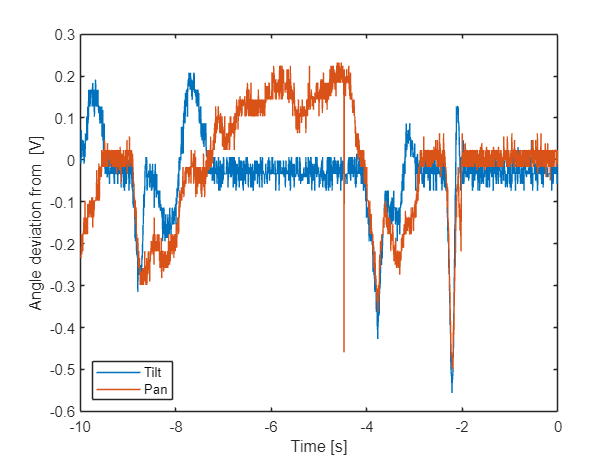

clear all;
clc;
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("D:\scope_rb6_2.csv", opts); 
scoperb62(:,"VarName2") = scoperb62(:,"VarName2")-1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3")-1.65;

plot(scoperb62,"xaxis","VarName2")
hold on
plot(scoperb62,"xaxis","VarName3")
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt','Pan'},'Location','southwest')
hold off;

## Clear temporary variables

clear opts